# Fluids Lab 2 COMSOL & CFD

% Import Data
data = xlsread('Fluids Lab2 Data.xlsx');
data = data(6:end,:);

% Reynold's No 0.001 - Silicone Oil
Re001_pr = data(:,2); % Pascals, experimental pressure
Re001_p0 = 0.011132; % Pascals, inlet pressure
Re001_dp = Re001_pr - Re001_p0; % Delta P
Re001_df = 0.0011712; % Newtons, drag force
Re001_U = 0.00051; % Meters/second, velocity
Re001_No = 0.001; % Reynold's No.

% Reynold's No 0.01 - Silicone Oil
Re01_pr = data(:,4); % Pascals, experimental pressure
Re01_p0 = 1.1104; % Pascals, inlet pressure
Re01_dp = Re01_pr - Re01_p0; % Delta P
Re01_df = 0.011712; % Newtons, drag force
Re01_U = 0.0051; % Meters/second, velocity
Re01_No = 0.01; % Reynold's No.

% Reynold's No 100
Re100_pr = data(:,6); % Pascals, experimental pressure
Re100_p0 = 3.5498*(10)^(-4); % Pascals, inlet pressure
Re100_dp = Re100_pr - Re100_p0; % Delta P
Re100_df = 4.3529*(10)^(-6); % Newtons, drag force
Re100_U = 0.005; % Meters/second, velocity
Re100_No = 100; % Reynold's No.

% Reynold's No 1000
Re1000_pr = data(:,8); % Pascals, experimental pressure
Re1000_p0 = 0.025955; % Pascals, inlet pressure
Re1000_dp = Re1000_pr - Re1000_p0; % Delta P
Re1000_df = 1.7269*(10)^(-4); % Newtons, drag force
Re1000_U = 0.05; % Meters/second, velocity
Re1000_No = 1000; % Reynold's No.

% Material Properties
sil_mu = 10; % Viscosity of silicone oil, Pa*s
sil_rho = 971; % Density of silicone oil, kg/m^3
wat_mu = 0.001; % Viscosity of water, Pa*s
wat_rho = 1000; % Density of water, kg/m^3
a = 0.01; % Radius of the sphere, m


## Analysis

% Calculate dimensionless groups
Re001_term = sil_mu * Re001_U/a;
Re001_dlg = Re001_dp/Re001_term;
Re01_term = sil_mu * Re01_U/a;
Re01_dlg = Re01_dp/Re01_term;
Re100_term = (1/2) * wat_rho * (Re100_U)^2;
Re100_dlg = Re100_dp/Re100_term;
Re1000_term = (1/2) * wat_rho * (Re1000_U)^2;
Re1000_dlg = Re1000_dp/Re1000_term;
phi = data(:,1)/a;


## Figure 2 Plot - Silicone Oil

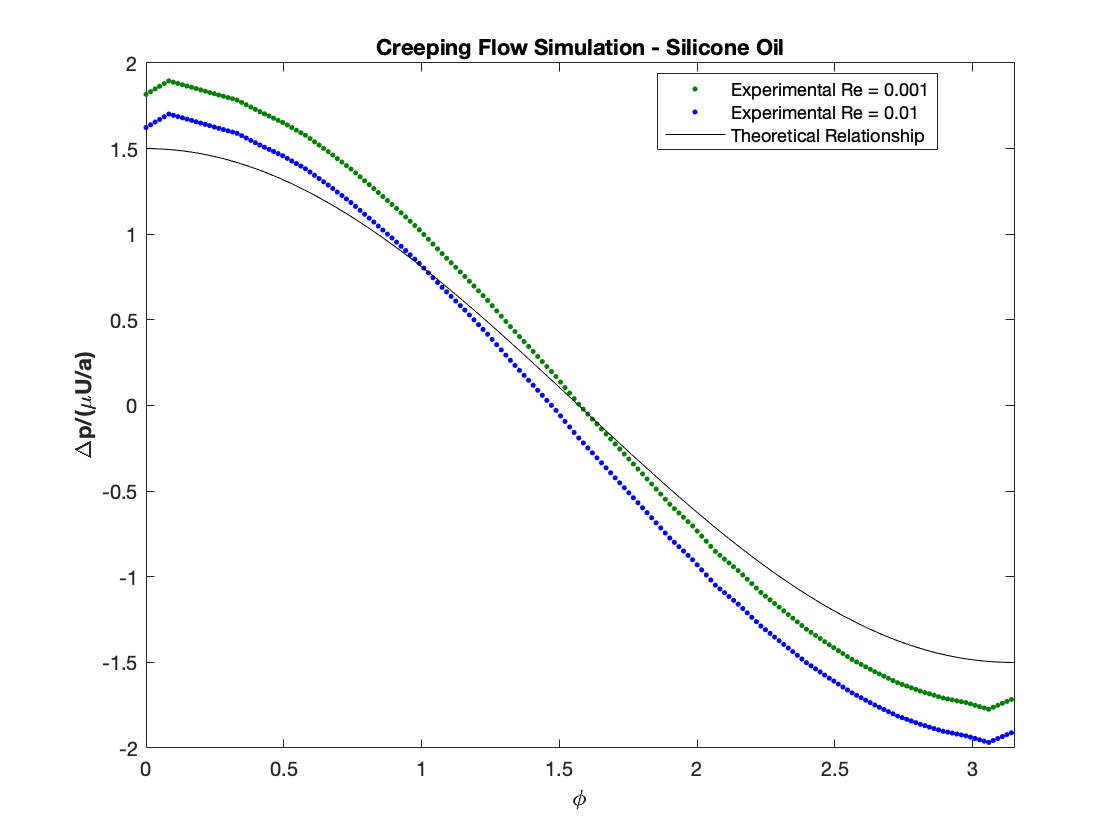

% Plot Re001, Re01, and theoretical
Re001_th = (3/2)*cos(phi);
plot(phi, Re001_dlg, '.', 'Color', [0 0.5 0])
title('Creeping Flow Simulation - Silicone Oil')
xlabel('\phi', "FontWeight","bold")
ylabel('\Deltap/(\muU/a)', 'FontWeight',"bold")
axis([0 3.15 -2 2])
hold on
plot(phi, Re01_dlg, 'b.')
hold on
plot(phi, Re001_th, 'k-')
legend('Experimental Re = 0.001', 'Experimental Re = 0.01', 'Theoretical Relationship', 'Location', 'best')
hold off

## Figure 3 Plot - Water

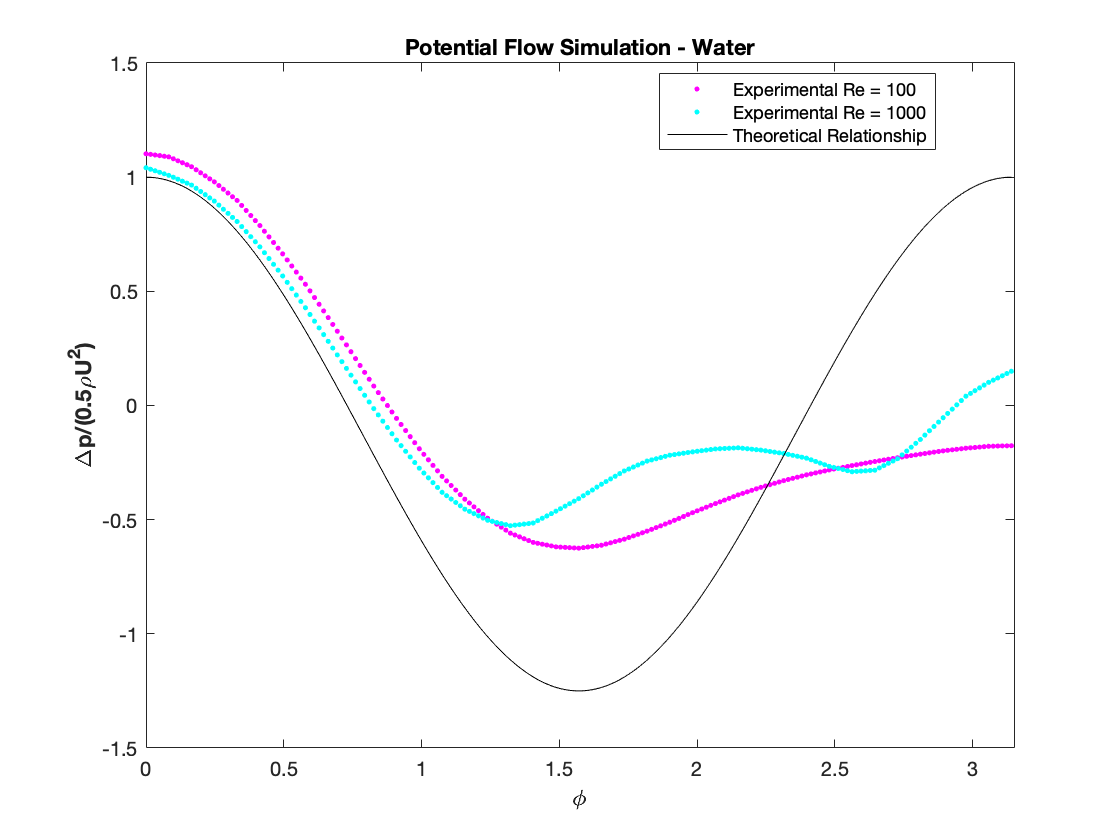

% Plot Re100, Re1000, and theoretical
Re100_th = 1 - (9/4)*((sin(phi)).^2);
plot(phi, Re100_dlg, 'm.')
title('Potential Flow Simulation - Water')
xlabel('\phi', "FontWeight","bold")
ylabel('\Deltap/(0.5\rhoU^{2})', 'FontWeight',"bold")
axis([0 3.15 -1.5 1.5])
hold on
plot(phi, Re1000_dlg, 'c.')
hold on
plot(phi, Re100_th, 'k-')
legend('Experimental Re = 100', 'Experimental Re = 1000', 'Theoretical Relationship', 'Location', 'best')
hold off

## Figure 4 Plot - C_d vs. Re

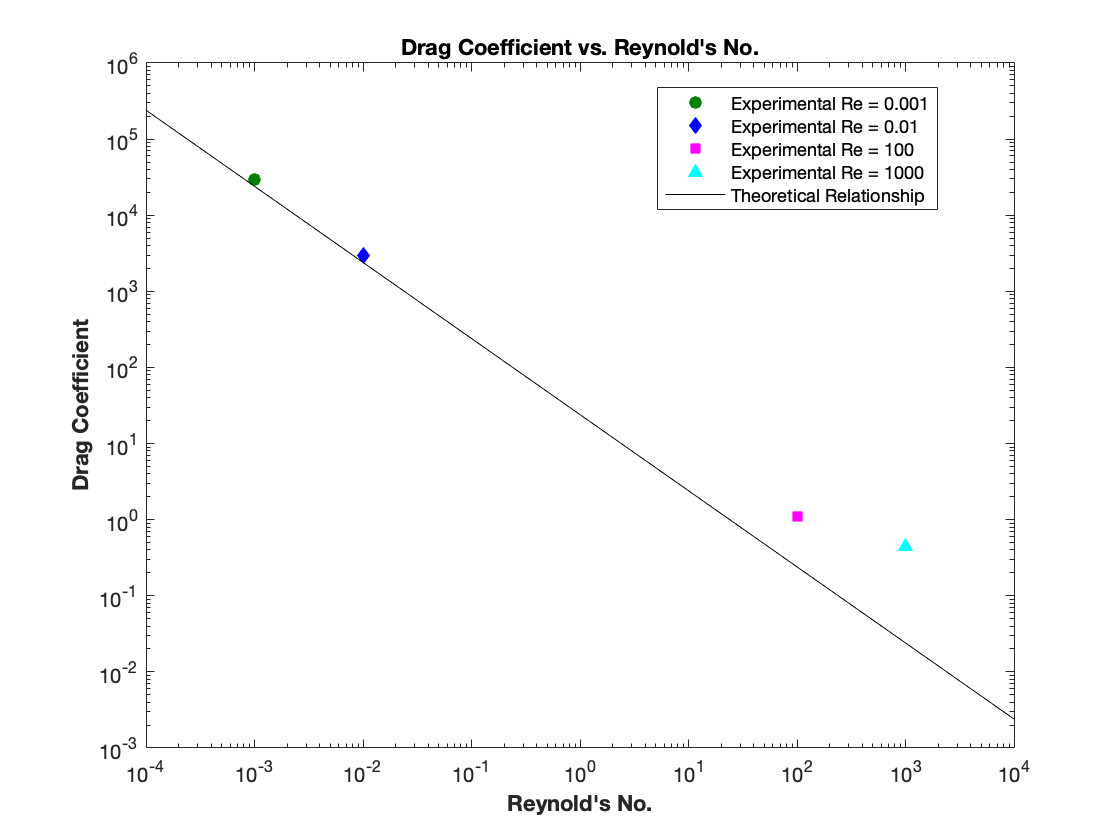

% Calculate drag coefficients
Re001_cd = calcdragcoeff(Re001_df, sil_rho, Re001_U, a);
Re01_cd = calcdragcoeff(Re01_df, sil_rho, Re01_U, a);
Re100_cd = calcdragcoeff(Re100_df, wat_rho, Re100_U, a);
Re1000_cd = calcdragcoeff(Re1000_df, wat_rho, Re1000_U, a);

dragco_vec = [Re001_cd Re01_cd Re100_cd Re1000_cd];
Re_vec = [Re001_No Re01_No Re100_No Re1000_No];
Re_line = [0.0001 Re_vec 10000]; % for the theoretical line (axes nicer)
CD = 24./Re_line;

% Plot drag coefficient vs. Re on log-log scale
count = 0;
for i = 1:length(Re_vec)
    count = count + 1;
    if count == 1
        sym = 'o';
        color = [0 0.5 0];
    elseif count == 2
        sym = 'd';
        color = 'b';
    elseif count == 3
        sym = 's';
        color = 'm';
    else
        sym = '^';
        color = 'c';
    end
    loglog(Re_vec(i), dragco_vec(i), sym, 'MarkerFaceColor', color, 'MarkerEdgeColor', color)
    hold on
end
loglog(Re_line, CD, 'k-')
xlabel('Reynold''s No.', 'fontweight','bold')
ylabel('Drag Coefficient', 'fontweight','bold')
title('Drag Coefficient vs. Reynold''s No.')
legend('Experimental Re = 0.001', 'Experimental Re = 0.01','Experimental Re = 100', ...
    'Experimental Re = 1000', 'Theoretical Relationship', 'Location',"best")
hold off

function out = calcdragcoeff(drag, rho, U, a)
% Calculates the drag coefficient based on the drag force, density,
% velocity, and radius  inputs
% Format: calcdragcoeff(drag_force, density, velocity, radius)
term = (1/2).*rho.*((U).^2).*pi.*a.^2;
out = drag./term;
end


function out = calcReNo(rho, U, a, mu)
% Calculates the dimensionless Reynold's number based on the density, velocity, radius,
% and viscosity inputs
% Formnat: calcReNo(density, velocity, radius, viscosity
out = 2.*rho.*U.*a./mu;
end
























